# Dynamic simulation using complementarity methods (II)

Author: Jiayin Xie 

Date: August 19 2020

### File structure

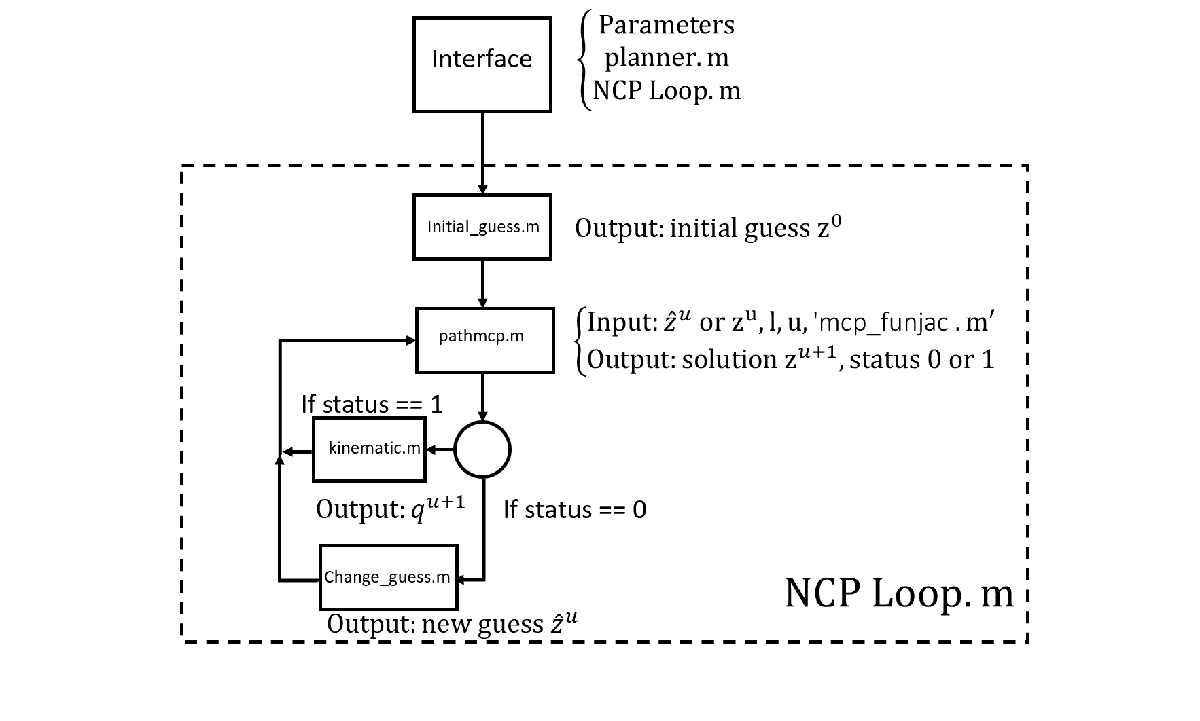

### Examples of a cube and ground

Interface script

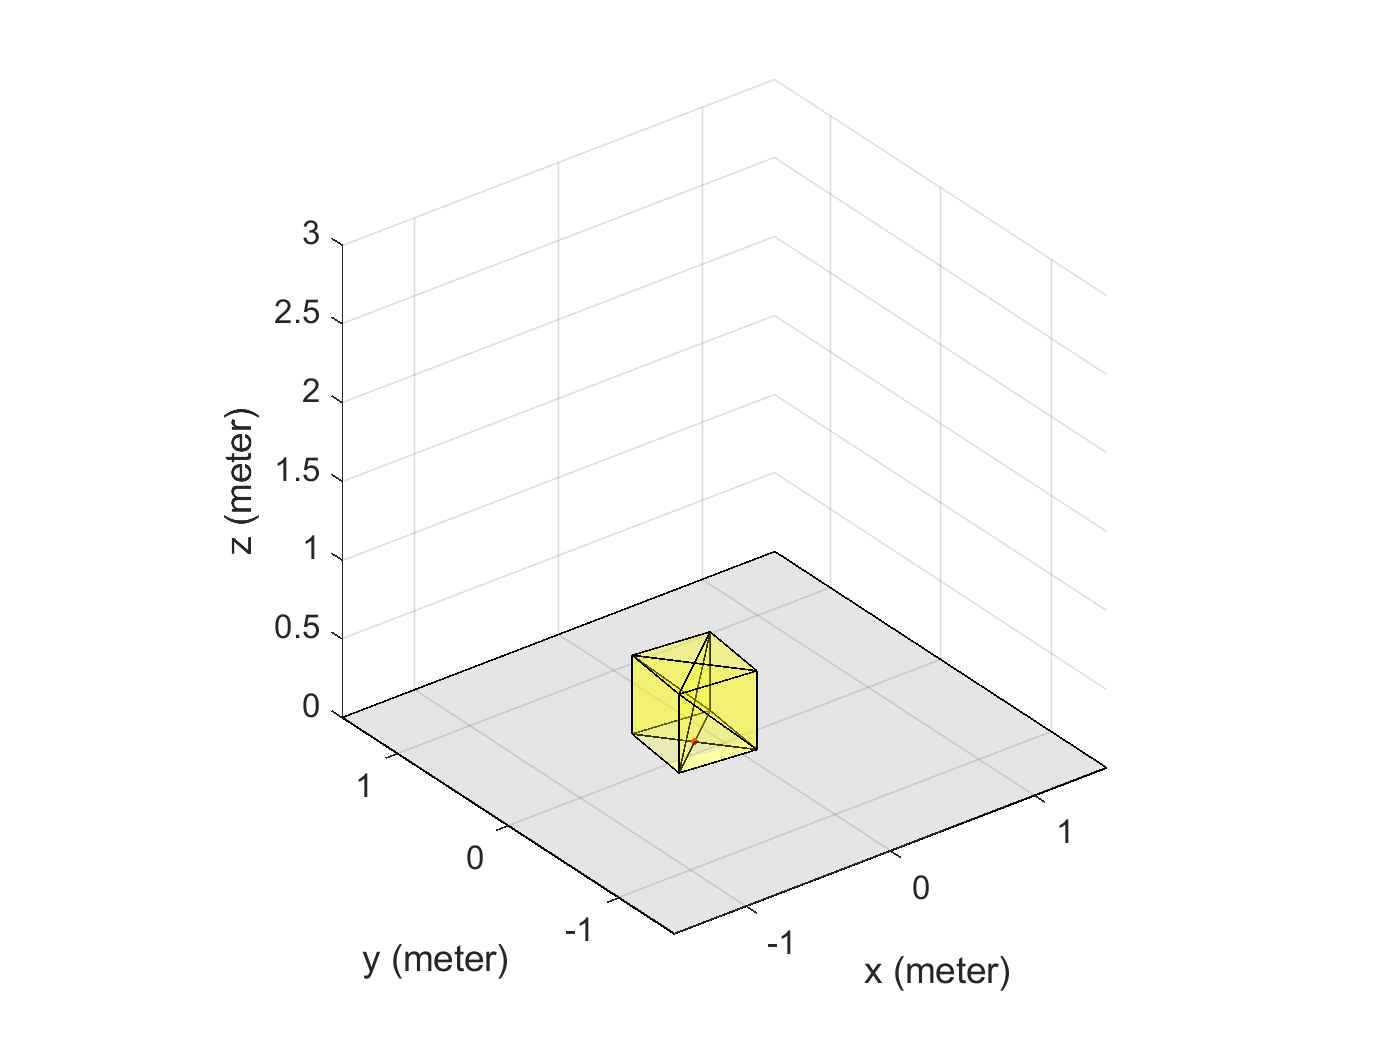

%% notation
% l - beginning of current time step
% l+1 - end of current time step
% If the error 'Jacobian has too many entries: update nnz in pathmcp.m'
% appears , you can modify the mod_N parameter in pathmcp.m file

clear all
cd('..');
addpath('convex_contact_patches_interface');
addpath('visualize');
addpath('utility');
addpath('funjac');
addpath('pathmexmaci64');

cd('convex_contact_patches_interface')
A = struct();
A.object = 'cube';
% mass of the object
A.mass = 3; %(kg)
A.gravity = 9.8; %(m/s^2)

% approximate dimension of the object 
A.dim=[0.5 0.5 0.5]; %(m) length width height

% friction model
A.ellipsoid = [1 1 0.1]; % the choice of e_r (m) depends on the CM
A.cof = 0.22;

% time step
A.h = 0.01; %(s)

% initial state and configuration
A.initial_q = [0;0;2;1;0;0;0]; % m
A.initial_v = [0;0;0;1;3;1];  %m/s

% unit
A.unit = 1; % 1 - m, 10 - dm, 100 - cm, 1000 - mm  

% impulses
A = planner_cuboid(A);
%N - the number of iteration



A = NCP_cuboid(A);

%movie_cuboid(A);